# Feature Convolution Network Demo

## Load Data

Load the Fisher iris data set. This data contains 150 observations with four input features representing the parameters of the plant and one categorical response representing the plant species. Each observation is classified as one of the three species: setosa, versicolor, or virginica. Each observation has four measurements: sepal width, sepal length, petal width, and petal length. 

filename = fullfile(toolboxdir('stats'),'statsdemos','fisheriris.mat');
load(filename)

Convert the numeric data to a table.

features = ["Sepal length","Sepal width","Petal length","Petal width"];

predictors = array2table(meas,"VariableNames",features);
trueLabels = array2table(categorical(species),"VariableNames","Response");

Create a table of training data whose final column is the response.

data = [predictors trueLabels];

Calculate the number of observations, features, and classes.

numObservations = size(predictors,1);
numFeatures = size(predictors,2);
numClasses = length(categories(data{:,5}));

## Split Data into Training, Validation, and Test Sets

Partition the data set into training, validation, and test sets. Set aside 15% of the data for validation and 15% for testing.

Determine the number of observations for each partition. Set the random seed to make the data splitting and CPU training reproducible.

rng('default');
numObservationsTrain = floor(0.7*numObservations);
numObservationsValidation = floor(0.15*numObservations);

Create an array of random indices corresponding to the observations and partition it using the partition sizes. 

idx = randperm(numObservations);
idxTrain = idx(1:numObservationsTrain);
idxValidation = idx(numObservationsTrain + 1:numObservationsTrain + numObservationsValidation);
idxTest = idx(numObservationsTrain + numObservationsValidation + 1:end);

Partition the table of data into training, validation, and testing partitions using the indices.

dataTrain = data(idxTrain,:);
dataVal = data(idxValidation,:);
dataTest = data(idxTest,:);

## Compare Network Architectures

Create a simple multi-layer perceptron. The feature input layer accepts data containing numeric scalars representing features, such as the Fisher iris data set.

numHiddenUnits = 5;
layers1 = [
    featureInputLayer(numFeatures, "Normalization", "rescale-symmetric")
    fullyConnectedLayer(numHiddenUnits)
    reluLayer
    fullyConnectedLayer(numClasses)
    softmaxLayer
    classificationLayer];

layers2 = [
    featureInputLayer(numFeatures, "Normalization", "rescale-symmetric")
    FeatConvLayer("FeatConv", numFeatures)
    fullyConnectedLayer(numHiddenUnits)
    reluLayer    
    fullyConnectedLayer(numClasses)
    softmaxLayer
    classificationLayer];

## Define Training Options and Train Network

Train the network using stochastic gradient descent with momentum (SGDM). Set the maximum number of epochs to 30 and use a mini-batch size of 15, as the training data does not contain many observations.

opts = trainingOptions("sgdm", ...
    "MaxEpochs",30, ...
    "MiniBatchSize",15, ...
    "Shuffle","every-epoch", ...
    "ValidationData",dataVal, ...
    "ExecutionEnvironment","cpu");

Train the network.

net = trainNetwork(dataTrain,layers1,opts);

Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:00 |       13.33% |        9.09% |       1.2041 |       1.2510 |          0.0100 |
|       8 |          50 |       00:00:00 |       80.00% |       77.27% |       0.7270 |       0.6404 |          0.0100 |
|      15 |         100 |       00:00:01 |       93.33% |       81.82% |       0.3362 |       0.3979 |          0.0100 |
|      22 |         150 |       00:00:02 |       93.33% |       90.91% |       0.2537 |       0.2996 |          0.

net2 = trainNetwork(dataTrain,layers2,opts);

Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:00 |       33.33% |       36.36% |       1.1435 |       1.1717 |          0.0100 |
|       8 |          50 |       00:00:01 |       93.33% |       72.73% |       0.4487 |       0.5134 |          0.0100 |
|      15 |         100 |       00:00:03 |       93.33% |       90.91% |       0.2918 |       0.3065 |          0.0100 |
|      22 |         150 |       00:00:05 |       93.33% |       95.45% |       0.2318 |       0.2285 |          0.

## Assess Network Performance

Classify observations from the test set using the trained network.

predictedLabels = net.classify(dataTest);
trueLabels = dataTest{:,end};

Visualize the results using a confusion matrix. 

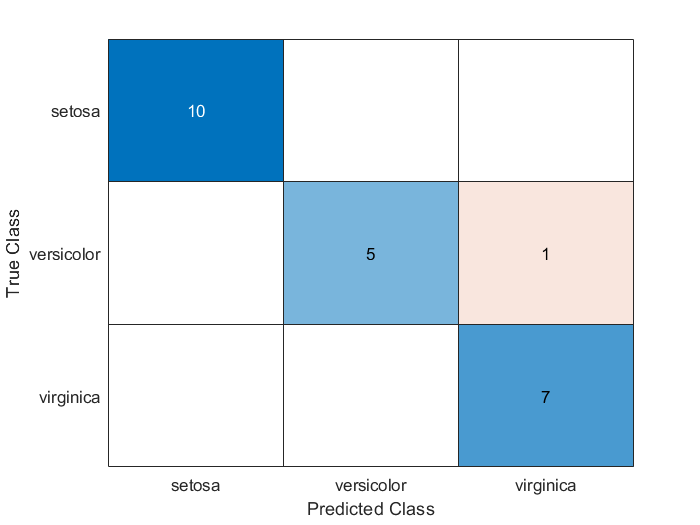

figure
confusionchart(trueLabels,predictedLabels)

The network successfully uses the four plant features to predict the species of the test observations.

Classify observations from the test set using the trained network2.

predictedLabels = net2.classify(dataTest);
trueLabels = dataTest{:,end};

Visualize the results using a confusion matrix. 

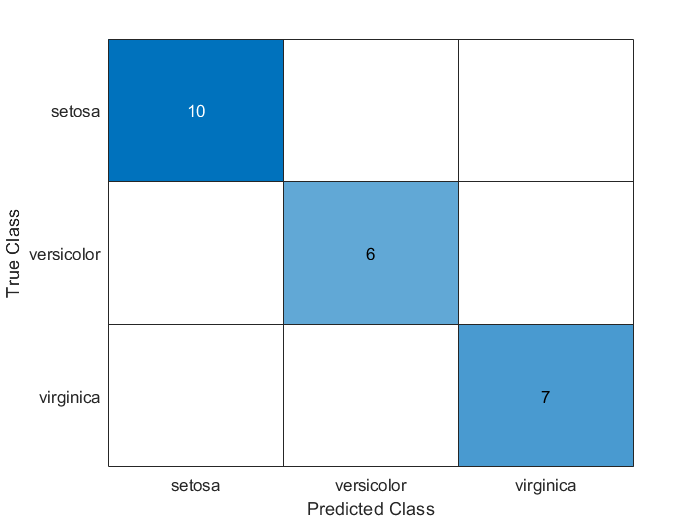

figure
confusionchart(trueLabels,predictedLabels)